## SimpleSonarRange.mlx

is an example of rading an analog sonar on an Arduino

hook analog out from sesnor into Pin A2, Vcc to 5 VDC, and gnd to gnd.

Program collects range voltrage data, plots it, and is terminated by operator input.

Braden and Dowling, 2-23-23, Revision 0

clc                                     % clear command window
clear                                   % clear MATLAB workspace

## Set up robot control system (code that runs once)

% create arduino ref-objects
[robotArduino, rawRangeIn0, rawRangeIn1, rawRangeIn2, blinkLED] = SETUPARDUINO('/dev/cu.usbmodem14101', 'Uno');

% Turn on board LED on and off to signal program has started
Blink(robotArduino, blinkLED, 5);
disp('Parking sonar activated')

Parking sonar activated


clc % clear command window

positionData = zeros(1, 3);


## Run Robot Control Loop (code that runs over and over)

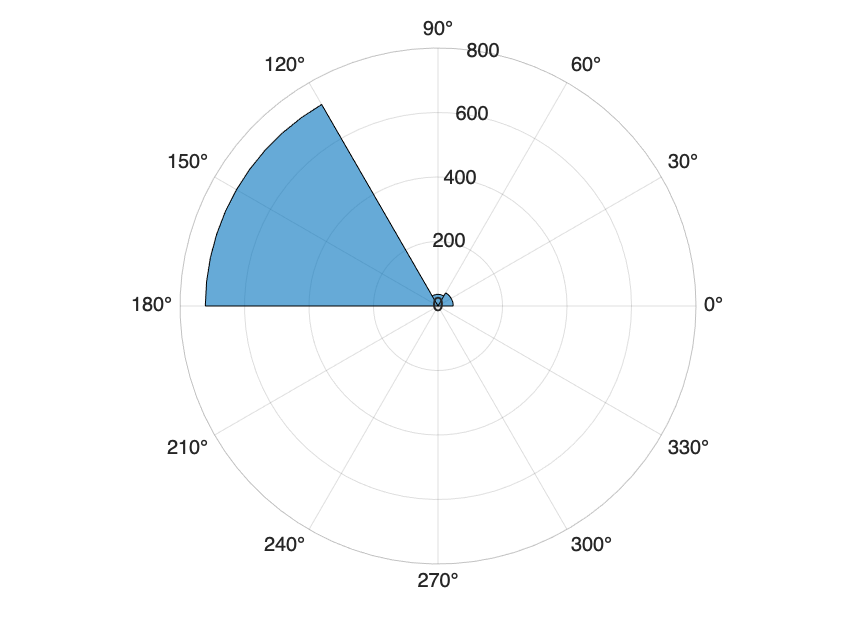

controlFlag = 1;                         
while (controlFlag < 2)
    distanceData = zeros(1, 3);
    rangeData=SENSE(robotArduino, rawRangeIn0);
    positionData(controlFlag, 1)=rangeData;
    distanceData(1,1)=(rangeData^2)*1895+14.21;
    rangeData=SENSE(robotArduino, rawRangeIn1);
    pause(0.6);
    positionData(controlFlag, 2)=rangeData;
    distanceData(1,2)=(rangeData^2)*1895+14.21;
    rangeData=SENSE(robotArduino, rawRangeIn2);
    pause(0.6);
    positionData(controlFlag, 3)=rangeData;
    distanceData(1,3)=(rangeData^2)*1895+14.21;
    polarhistogram('BinEdges',[0 pi/3 2*pi/3 pi],'BinCounts',[distanceData(1,3) distanceData(1,2) distanceData(1,1)]);
    positionData = zeros(1, 3);
                            
end

## Mission data processing 

## Clean shut down

clc
disp('Arduino program has ended');
clear robotArduino
beep

## Robot Functions (store this codes local functions here)

In practice for modularity, readability and longiteveity, your main robot code should be as brief

as possible and the bulk of the work should be done by functions

function [robotArduino, rawRangeIn0,rawRangeIn1, rawRangeIn2, blinkLED] = SETUPARDUINO(COMPORT, MODEL)
robotArduino = arduino(COMPORT, MODEL , 'Libraries', 'Servo');

% configure pin 13 as a digitial-out LED
blinkLED = 'D13';
configurePin(robotArduino, blinkLED, 'DigitalOutput');

% configure A0 pin as an analog input
rawRangeIn0 = 'A0';%left
rawRangeIn1 = 'A1';%middle
rawRangeIn2 = 'A2';%right

configurePin(robotArduino, rawRangeIn0, 'AnalogInput');
configurePin(robotArduino, rawRangeIn1, 'AnalogInput');
configurePin(robotArduino, rawRangeIn2, 'AnalogInput');

end

function [] = Blink(a,LED, n)
        for bIndex = 1:n
            writeDigitalPin(a, LED, 0);
            pause(0.2);
            writeDigitalPin(a, LED, 1);
            pause(0.2);
        end
end

## **Sense Functions (store all Snese related local functions here)**

function rangeData = SENSE(robotArduino, rawRangeIn)
    rangeData = readVoltage(robotArduino, rawRangeIn);
    
end

## Think Function (store all Think related local functions here)

function THINK()
    
end

## Act Functions (store all Act related local functions here)

function ACT(time)
    

end